# Wczytywanie danych z plików

Najbardziej elastyczną funkcją pozwalającą importować pliki jest [importdata()](https://www.mathworks.com/help/matlab/ref/importdata.html). Funkcja ta określa typ pliku na podstawie jego rozszerzenia. Poniżej przedstawiono i omówiono import kilku różnych plików. Niestety jej interpretacja danych czasami może nie być zgodna z naszymi oczkiewaniami.

Używając funkcji import data w odniesieniu do pliku tekstowego dane zostaną zaimportowane jako macierz tylko jeżeli wszyskie dane są tego samego typu (np. liczbowego, tekstowego, itp.). 

dane1 = importdata("dane1.txt")

dane1 =     0.6447    0.1842    0.0923    0.9674    0.8760    0.4789    0.2050
    0.2374    0.6673    0.8351    0.1048    0.9527    0.2345    0.3584
    0.8091    0.1290    0.1801    0.3724    0.5887    0.9361    0.7149
    0.2535    0.2997    0.2584    0.8066    0.6273    0.0139    0.7800
    0.0005    0.0871    0.0667    0.2961    0.3370    0.2471    0.6219
    0.4030    0.1062    0.8859    0.4310    0.8775    0.2179    0.7560
    0.6925    0.7844    0.4785       NaN    0.5765    0.2603    0.0399
    0.7689    0.1560    0.7503    0.6630    0.4908    0.4448    0.8120
    0.8175    0.4214    0.3437    0.8294    0.3783    0.3575    0.0029
    0.8793    0.5452    0.6055    0.3068    0.4389    0.3496    0.7696


Jeżeli jednak dane w kolumnach są różnego typu zostaną zaimportowane jako cell array, w którym w każdej komórce znajduje się pojedynczy wiersz z pliku.

dane2 = importdata("dane2.txt")

dane2 = 10×1 cell array
    {'A→B→C'                    }
    {'0.718607677→0.079663512→a'}
    {'0.178924653→0.416613225→a'}
    {'0.498539108→0.073126413→c'}
    {'0.16126931→0.631241813→b' }
    {'0.556407397→0.963685667→a'}
    {'0.675988901→0.810381368→c'}
    {'0.808333848→0.53562721→c' }
    {'0.792891362→0.215301064→a'}
    {'0.565031258→0.526449911→b'}


dane2{1:3}

ans = 'A	B	C'

ans = '0.718607677	0.079663512	a'

ans = '0.178924653	0.416613225	a'

Najprostszym rozwiązaniem takiej sytuacji, o ile dane mają format tabeli, jest użycie funkcji [readtable()](https://www.mathworks.com/help/matlab/ref/readtable.html), która zwróci obiekt ramki danych, w których kolumny będą zawierały dane różnego typu.

dane2t = readtable("dane2.txt")

dane2t = 9×3 table
       A          B          C  
    _______    ________    _____

    0.71861    0.079664    {'a'}
    0.17892     0.41661    {'a'}
    0.49854    0.073126    {'c'}
    0.16127     0.63124    {'b'}
    0.55641     0.96369    {'a'}
    0.67599     0.81038    {'c'}
    0.80833     0.53563    {'c'}
    0.79289      0.2153    {'a'}
    0.56503     0.52645    {'b'}


Funkcję readtable() można wykorztsać również do wczytania danych z arkuszy kalkulacyjnych.

dane3t = readtable("dane3.xlsx","Sheet","Arkusz2")

ans = 30×2 table
    Var1     Var2 
    ____    ______

      1       2.59
      2     4.3349
      3     6.4531
      4     8.7995
      5     10.293
      6     12.058
      7     14.766
      8     16.484
      9     18.704
     10     20.681
     11      22.57
     12     24.179
     13     26.806
     14     28.505
     15     30.271
     16     32.143


Natomiast w przypadku użycia funkcji importdata() do arkusza kalkulacyjnego wczytane zostaną wszystkie dane, a wynikiem takiej operacji będzie struktura, której polami są dane wczytane z poszczególnych arkuszy. Dostęp do poszczególnych arkuszy uzyskuje się jak w przypadku zwykłej struktury - czyli z wykorzystaniem operatora kropki.

dane3xls = importdata("dane3.xlsx")

dane3xls = struct with fields:
    Arkusz1: [11×7 double]
    Arkusz2: [30×2 double]


M1 = dane3xls.Arkusz1

M1 =     0.6447    0.1842    0.0923    0.9674    0.8760    0.4789    0.2050
    0.2374    0.6673    0.8351    0.1048    0.9527    0.2345    0.3584
    0.8091    0.1290    0.1801    0.3724    0.5887    0.9361    0.7149
    0.2535    0.2997    0.2584    0.8066    0.6273    0.0139    0.7800
    0.0005    0.0871    0.0667    0.2961    0.3370    0.2471    0.6219
    0.4030    0.1062    0.8859    0.4310    0.8775    0.2179    0.7560
    0.6925    0.7844    0.4785    0.9350    0.5765    0.2603    0.0399
    0.7689    0.1560    0.7503    0.6630    0.4908    0.4448    0.8120
    0.8175    0.4214    0.3437    0.8294    0.3783    0.3575    0.0029
    0.8793    0.5452    0.6055    0.3068    0.4389    0.3496    0.7696


M2 = dane3xls.Arkusz2

M2 =     1.0000    2.5900
    2.0000    4.3349
    3.0000    6.4531
    4.0000    8.7995
    5.0000   10.2928
    6.0000   12.0584
    7.0000   14.7661
    8.0000   16.4843
    9.0000   18.7036
   10.0000   20.6810


Powyższe metody dobrze nadają się do pracy z danymi o prostej strukturze tabelarycznej. Matlab oferuje wiele specjalistycznych funkcji do importu niestandardowych typów danych np. plików shape często wykorzystywanych w geodezji. W tym celu należy użyć funkcji [shaperead()](https://www.mathworks.com/help/map/ref/shaperead.html). (Dane pobrano ze strony [GIS Support](https://gis-support.pl/baza-wiedzy-2/dane-do-pobrania/granice-administracyjne/).)

dane_shp = shaperead("Wojewodztwa/Województwa.shp")

dane_shp = 16×1 struct array with fields:
    Geometry
    BoundingBox
    X
    Y
    JPT_SJR_KO
    JPT_KOD_JE
    JPT_NAZWA_
    JPT_ORGAN_
    JPT_JOR_ID
    WERSJA_OD
    WERSJA_DO
    WAZNY_OD
    WAZNY_DO
    JPT_KOD__1
    JPT_NAZWA1
    JPT_ORGAN1
    JPT_WAZNA_
    ID_BUFORA_
    ID_BUFORA1
    ID_TECHNIC
    IIP_PRZEST
    IIP_IDENTY
    IIP_WERSJA
    JPT_KJ_IIP
    JPT_KJ_I_1
    JPT_KJ_I_2
    JPT_OPIS
    JPT_SPS_KO
    ID_BUFOR_1
    JPT_ID
    JPT_KJ_I_3
    Shape_Leng
    Shape_Area


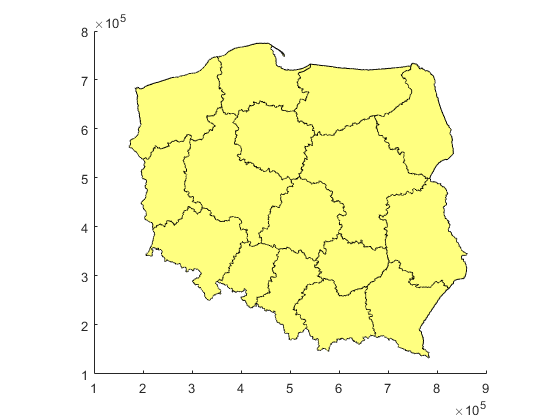

newplot()
mapshow(dane_shp)

# Zapis danych w plikach

Zapisywanie danych do plików jest analogiczne do ich wczytywania. W celu zapisu danych do plików wykorzystuje się funkcje analogiczne jak w przypadku ich wczytywania, lecz posiadajace w nazwie 'write' zamiast 'read' np. [writetable()](https://www.mathworks.com/help/matlab/ref/writetable.html).

Najprostszą funkcją do zapisu danych jest funkcja [writematrix()](https://www.mathworks.com/help/matlab/ref/writematrix.html), która zapisuje dane w wybranym formacie np.: pliku tekstowym, pliku tekstowym CSV, czy pliku arkusza kalkulacyjnego.

dane_do_zapisu = [(1:5).',rand(5,4) ]

dane_do_zapisu =     1.0000    0.8905    0.0885    0.7227    0.6538
    2.0000    0.7990    0.7984    0.1104    0.7491
    3.0000    0.7343    0.9430    0.1175    0.5832
    4.0000    0.0513    0.6837    0.6407    0.7400
    5.0000    0.0729    0.1321    0.3288    0.2348


**Uwaga: plik zostanie zapisany w bieżącym folderze (okienko *****Current folder***** po lewej stronie).**

writematrix(dane_do_zapisu,"zapisane_dane.txt") % zapis do pliku tekstowego
writematrix(dane_do_zapisu,"zapisane_dane.csv") % zapis do pliku tekstowego CSV
writematrix(dane_do_zapisu,"zapisane_dane.xlsx") % zapis do pliku arkusza kalkulacyjnego

Aby zapisać dane w formacie tabeli konieczne jest utworzenie tabeli np. przy użyciu funkcji table().

writetable(table(dane_do_zapisu),"zapisane_dane_tabela.csv")  % zapis do pliku tekstowego CSV
writetable(table(dane_do_zapisu),"zapisane_dane_tabela.xlsx") % zapis do pliku arkusza kalkulacyjnego

Ten format daje większe możliwości niż 

% utworzenie syntetycznych danych
ix = (1:5).';
x = linspace(0,10,5).';
y = x.^2;
alfabet ='A':'Z';
kategoria=(s(randi(numel(s),[length(x),1]))).';
% utworzeni wynikowej tabeli
tabela = table(ix,x,y,kategoria)

tabela = 5×4 table
    ix     x       y      kategoria
    __    ___    _____    _________

    1       0        0        H    
    2     2.5     6.25        J    
    3       5       25        I    
    4     7.5    56.25        A    
    5      10      100        D    


writetable(tabela,"tabela.xlsx")